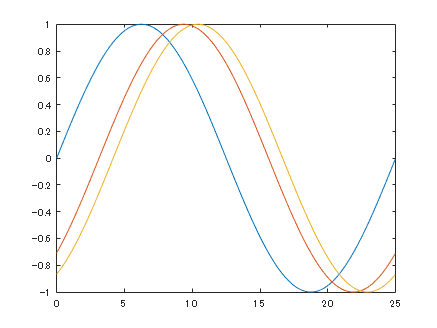

Fs = 30;
T = 1/Fs;
L = 750;
t = (0:L-1)*T;
ff = Fs*(0:(L/2))/L;

% 刺激がpi/4だとする [pi/4 pi/2 7*pi/12]
x = [cos(2*pi/25*t-pi/2); cos(2*pi/25*t-pi*3/4); cos(2*pi/25*t-pi*5/6)];
plot(t,x)


fourier = fft(x');
first_harmonic = fourier(2,:);
phase_angle = angle(first_harmonic);

phase_angle*180/pi

ans =   -90.0000 -135.0000 -150.0000


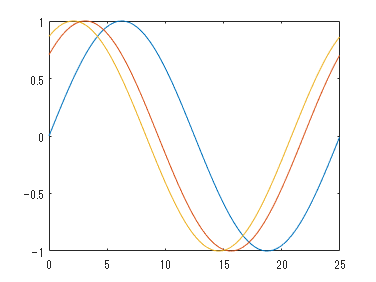

% 刺激が逆向き [7*pi/4 3*pi/2 17*pi/12]
y = [sin(2*pi/25*t-2*pi); sin(2*pi/25*t-7*pi/4); sin(2*pi/25*t-20*pi/12)];
plot(t,y)


fourier = fft(y');
first_harmonic = fourier(2,:);
phase_angle = angle(first_harmonic);

phase_angle*180/pi

ans =   -90.0000  -45.0000  -30.0000


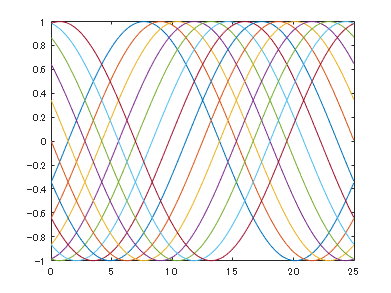

Fs = 30;
T = 1/Fs;
L = 750;
t = (0:L-1)*T;
ff = Fs*(0:(L/2))/L;

% 刺激がpi/2だとする
sigeki = pi/4;
sigekis = ((20:20:280).*pi/180)';
x = cos(2*pi/25*t-sigekis-pi/2);
plot(t,x)


fourier = fft(x');
first_harmonic = fourier(2,:);
phase_angle = angle(first_harmonic);

a = phase_angle;
d = find(a>-90*pi/180);
a(d) = a(d)-2*pi;
a*180/pi

ans =  -110.0000 -130.0000 -150.0000 -170.0000 -190.0000 -210.0000 -230.0000 -250.0000 -270.0000 -290.0000 -310.0000 -330.0000 -350.0000 -370.0000


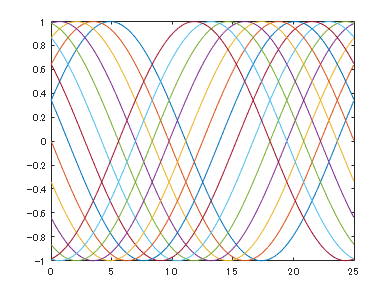

% 刺激が逆向き 3*pi/2
y = cos(2*pi/25*t-(2*pi-sigekis)-pi/2);
plot(t,y)


fourier = fft(y');
first_harmonic = fourier(2,:);
phase_angle = angle(first_harmonic);

b = phase_angle;
d = find(b>-150*pi/180);
b(d) = b(d)-2*pi;
b*180/pi

ans =  -430.0000 -410.0000 -390.0000 -370.0000 -350.0000 -330.0000 -310.0000 -290.0000 -270.0000 -250.0000 -230.0000 -210.0000 -190.0000 -170.0000


disp('results')

results


c = (b-a)./2+pi;
c*180/pi

ans =    20.0000   40.0000   60.0000   80.0000  100.0000  120.0000  140.0000  160.0000  180.0000  200.0000  220.0000  240.0000  260.0000  280.0000


sigekis'*180/pi

ans =    20.0000   40.0000   60.0000   80.0000  100.0000  120.0000  140.0000  160.0000  180.0000  200.0000  220.0000  240.0000  260.0000  280.0000


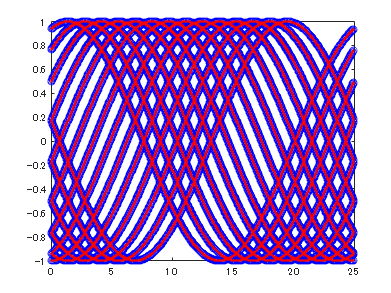

real = cos(2*pi/25*t-sigekis);
predict = cos(2*pi/25*t-c');

plot(t,real,'ob')
hold on;
plot(t,predict,'.r')
hold off;